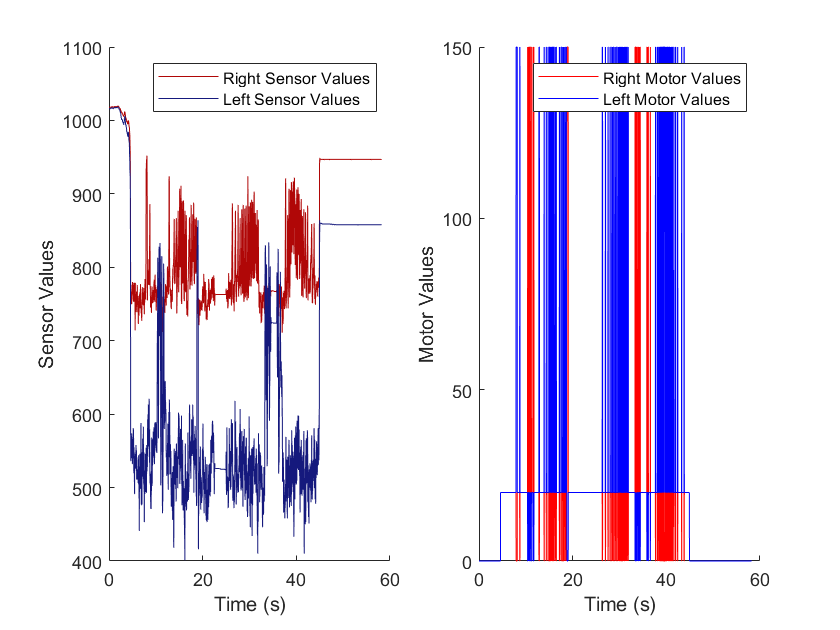

data = csvread("serial_data.csv");

t = linspace(0, 58.22, 2912);
right_sensor = data(:, 1);
left_sensor = data(:, 2);
right_wheel = data(:, 3);
left_wheel = data(:, 4);

clf
subplot(1, 2, 1);
xlabel("Time (s)")
ylabel("Sensor Values")
hold on
plot(t, right_sensor, 'Color', '#b00707', "LineStyle", '-')
plot(t, left_sensor, 'Color', '#15197d', "LineStyle", '-')
legend("Right Sensor Values", "Left Sensor Values")
hold off


subplot(1, 2, 2);
xlabel("Time (s)")
ylabel("Motor Values")
hold on
plot(t, right_wheel, 'Color', '#ff0000', "LineStyle", '-')
plot(t, left_wheel, 'Color', '#0000ff', "LineStyle", '-')
legend("Right Motor Values", "Left Motor Values")

hold off